## Step 1. Straigten and cut the images

The script also includes converting from RGB to b&w. Saves both the straighten and the cut.

clearvars

DATA_PATH = 'data';
STRAIGHTEN_PATH = [DATA_PATH '/precut_warp'];
CUT_PATH = [DATA_PATH '/cut_warp_disp_flip'];

% d = table(1, 1375, 0, 1, 1024);
d = table(1, 1375, 211, 415, 1024);
d.Properties.VariableNames = ["image", "black", "disp", "top", "right"];

cut_straight

## Step 2. Stitch the images

The script stitches the image into one (I).

clearvars

DATA_PATH = 'data';
CUT_PATH = [DATA_PATH '/cut_warp_disp_flip'];

r_record = 5.3;
theta = 3.17;
% chord is approx of the horizontal displacement in mm
chord = 2 * r_record * sind(theta/2) * 10;
pixels_per_mm = 207;

stitching

   100

   110



h = figure;
imshow(I(:, 1: 1 + 5000))
axis tight manual, ax = gca; ax.NextPlot = 'replaceChildren';
M(round((size(I, 2)-5000)/300)) = struct('cdata', [], 'colormap', []);
h.Visible = 'off';

for i = 1: 300: size(I, 2)

        if i + 5000 > size(I, 2)
            break
        end
        
        done = floor(i / size(I, 2));
        imshow(I(:, i: i + 5000))
        title([char(ones(1, done) * '*') char(ones(1, 10-done) * '-')])
        drawnow
        M(i) = getframe;
end
h.Visible = 'on';

show = strcmp(input('show? [y/n] ', 's'), 'y');
if show
    movie(M)
end

## Step 3. Detect groove

The script detects the groove and manipulates it.

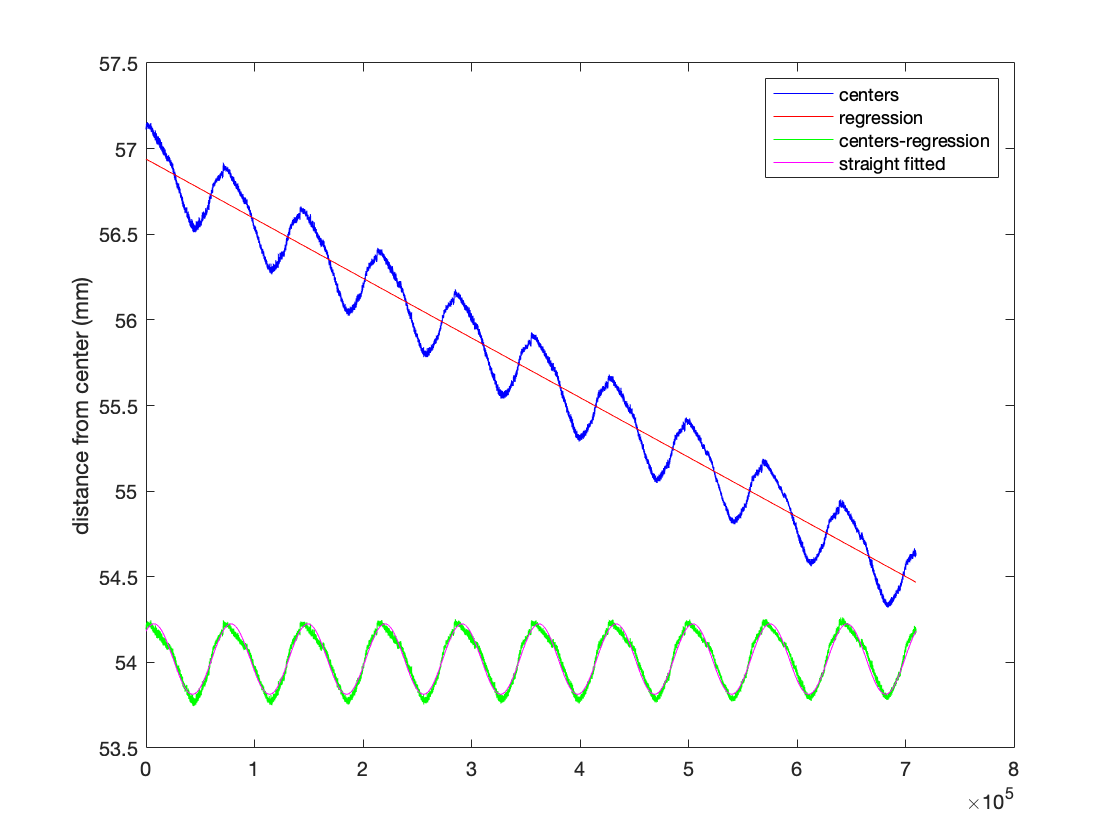

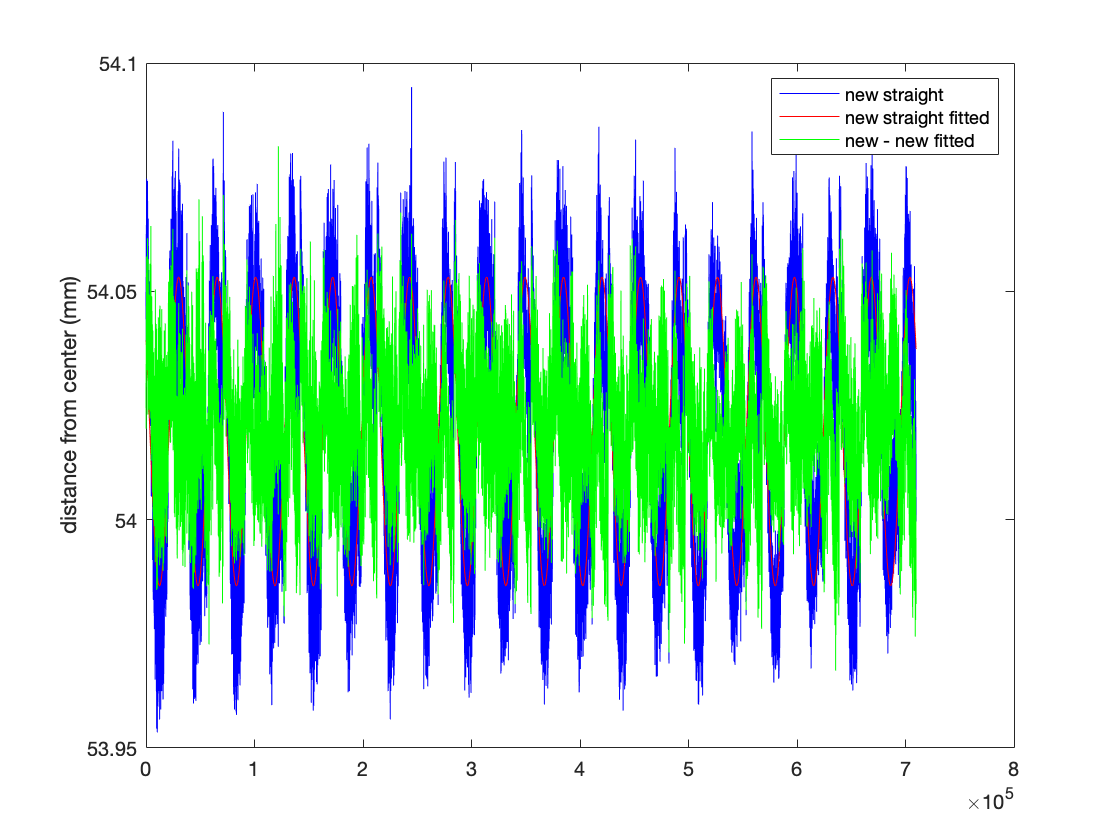

clearvars -except CUT_PATH r_record pixels_per_mm stitch_data I H M

groove_h = 25; % estimated groove height
n_rev = 10;
% init_rev_col = 492;
init_rev_col = 633;
cut_data = readtable([CUT_PATH '/where.csv']);
d = cut_data(1, :); % assuming equal cuts for all

% black radius in mm + d.disp in mm + init_rev_col in mm
start_mm = r_record * 10 + d.disp / pixels_per_mm;

groove_detection_continuous

% soundsc(straight, Fs), pause(time+1)
% soundsc(new_straight, Fs), pause(time+1)
soundsc(final, Fs)

clearvars -except CUT_PATH stitch_data I H M S I_ I_show centers line straight ...
    straight_fitted new new_straight straight_fitted2 final Fs